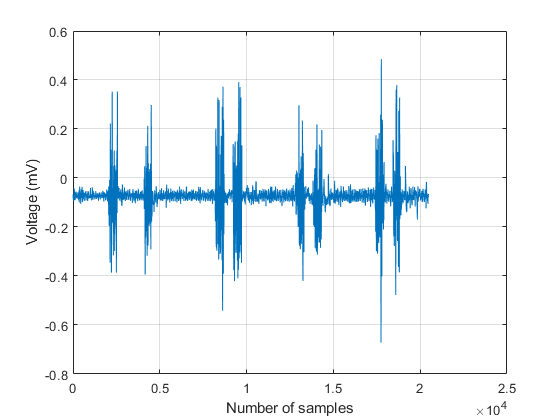

%-------------------------------------------------------------------------%
%  Electromyography (EMG) Feature Extraction source codes demo version    %
%                                                                         %
%  Programmer: Jingwei Too                                                %
%                                                                         %
%  E-Mail: jamesjames868@gmail.com                                        %
%-------------------------------------------------------------------------%

clc, clear, close
% Generate a sample random signal 
% f=1000; % Sampling frequency 
% Ts=1/f; % Period
% t=0:Ts:0.25; 
% X=0.01*(cos(2*pi*f*t)+randn(1,length(t))); % Signal
[X, f] = audioread("../one&two.wav");
X = X(:,1);
% Plot sample signal
plot(X); xlabel('Number of samples'); ylabel('Voltage (mV)'); grid on; 


%---Input------------------------------------------------------------------
% X:     EMG signal (1 x samples)
% thres: Threshold value
%---Output-----------------------------------------------------------------
% f:     Feature
% feat:  Feature vector 
%--------------------------------------------------------------------------

(1) Enhanced Mean absolute value

f1=jEMAV(X)

f1 = 0.2056

% (2) Enhanced Wavelength
f2=jEWL(X)

f2 = 665.3673

% (3) Mean absolute value
f3=jMAV(X)

f3 = 0.0854

% (4) Wavelength
f4=jWL(X)

f4 = 112.7221

% (5) Zeros Crossing
thres=0.01; f5=jZC(X,thres)

f5 = 163

% (6) Slope Sign Change
thres=0.01; f6=jSSC(X,thres)

f6 = 132

% (7) Root Mean Square
f7=jRMS(X)

f7 = 0.1002

% (8) Average Amplitude Change
f8=jAAC(X)

f8 = 0.0055

% (9) Difference Absolute Standard Deviation Value
f9=jDASDV(X)

f9 = 0.0122

% (10) Log Detector
f10=jLD(X)

f10 = 0.0749

% (11) Modified Mean Absolute Value
f11=jMMAV(X)

f11 = 0.0642

% (12) Modified Mean Absolute Value 2
f12=jMMAV2(X)

f12 = 0.0427

% (13) Myopulse Percentage Rate 
thres=0.016; f13=jMYOP(X,thres)

f13 = 0.9844

% (14) Simple Square Integral 
f14=jSSI(X)

f14 = 205.4198

% (15) Variance of EMG 
f15=jVAR(X)

f15 = 0.0100

% (16) Willison Amplitude
thres=0.01; f16=jWAMP(X,thres)

f16 = 2664

% (17) Maximum Fractal length 
f17=jMFL(X)

f17 = 0.5544


% Feature vector
feat=[f1,f2,f3,f4,f5,f6,f7,f8,f9,f10,f11,f12,f13,f14,f15,f16,f17]

feat = 	1.0e+03 *

    0.0002    0.6654    0.0001    0.1127    0.1630    0.1320    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0010    0.2054    0.0000    2.6640    0.0006
